# Plot Sensitivities

- Load the symbolic char parameters and the sensitivities to plot

- Plot Sensitivities

#### Step 1

clear; 
clear all;

addpath("functions/");
Parameters;
load("mats/SIE_X_Means.mat", "SIE_X_Means");
load("mats/SIE_X_Sensitivities.mat", "SIE_X_Sens");
load("mats/AIE_X_Means.mat", "AIE_X_Means");
load("mats/AIE_X_Sensitivities.mat", "AIE_X_Sens");


muscles = {'DELT1', 'DELT2', 'DELT3', 'PECM2', 'BIClong', 'BICshort', 'TRIlong', 'TRIlat', 'BRA', 'BRD', 'PT', 'FCR', 'FCU', 'ECR', 'ECU'};
ms = {1, muscles{1}; 2, muscles{2}; 3, muscles{3}; 4, muscles{4}; 5, muscles{5}; 6, muscles{6}; 7, muscles{7}; 8, muscles{8}; 9, muscles{9}; 10, muscles{10}; 11, muscles{11}; 12, muscles{12}; 13, muscles{13}; 14, muscles{14}; 15, muscles{15}};

%% Find the highest sensitivities
all_aie = [];

for m = 1:length(AIE_X_Sens)
    matrices = AIE_X_Sens{m};
    for pm = 1:size(matrices, 1)
        for wm = 1:size(matrices, 2)
            all_aie = [all_aie, matrices{pm, wm}];
        end
    end
end

all_aie = sort(all_aie, "ascend");
all_aie(length(all_aie) - 19: length(all_aie))

ans =     1.9837    2.0283    2.0530    2.0619    2.1051    2.1135    2.1549    2.2108    2.2118    2.2462    2.2675    2.3809    2.4030    2.4056    2.4927    2.5024    2.7631    3.1167    4.2955    4.6735


#### Step 2

Now that we have loaded the sensitivities and necessary character values, we can plot the:

- SIE and AIE sensitivies

- Means of SIE and AIE - Heatmap, ascending order of parameter influence

#### SIE and AIE Sensitivities

% SIE and AIE
sens_x_plot(SIE_X_Sens, "Single Input Excitation Sensitivities at " + ms{1, 2}, params_char, ms{1, 1});

Plotting single and all input excitation sensitivities


sens_x_plot(AIE_X_Sens, "All Input Excitation Sensitivities", params_char, 0);

We just plotted the sensitivities, now lets plot their means so we can analyze which parameters have the most effect in the tremor band.

#### SIE and AIE Mean Sensitivities

% Go into individual sensitivities

mean_x_plot(SIE_X_Means, "Mean of Single Input Excitation Sensitivities", params_char);
mean_x_plot(AIE_X_Means, "Means of All Input Excitation Sensitivities", params_char);

**SIE Mean Sensitivities for All Muscles**

% Take the sensitivities and find the mean of each parameter at each DOF
band_start = 40;

Plotting means of single and all input excitation sensitivities


    0.4273



band_end = 80;

    0.6636



means = [];


% ps = parameter sensitivities
for ps = 1:length(SIE_X_Sens) 
    sens = SIE_X_Sens{ps};

    % p = parameter, which corresponds to rows
    for p = 1:size(sens, 1)
        param_sens = [];
        
        % w = the frequency column, do this between the tremor band
        % where the tremor band is between 4-8 Hz
        for w = band_start:band_end
            % Now we need to access individual sensitivity vectors
            param_sens = [param_sens; sens(p, w)];
        end
        params = cell2mat(param_sens);
        means = [means; mean(params)];
    end
end

% Let's plot the data where each column of each row of the `means` will be the y
% and each row corresponds to a parameters
imagesc(means.');
set(gca, 'XTick', 1:numel(params_char), 'XTickLabel', params_char);
set(gca, 'YTick', 1:numel(muscles), 'YTickLabel', muscles);
title("Mean Total Output Sensitivities for Muscles"); 
colormap("turbo");
colorbar;

**SIE Standard Deviation for All Muscles**

band_start = 40;
band_end = 80;
stds = [];

% ps = parameter sensitivities
for ps = 1:length(SIE_X_Sens) 

    sens = SIE_X_Sens{ps};

    % p = parameter, which corresponds to rows
    for p = 1:size(sens, 1)
        param_sens = [];
        
        % w = the frequency column, do this between the tremor band
        % where the tremor band is between 4-8 Hz
        for w = band_start:band_end
            % Now we need to access individual sensitivity vectors
            param_sens = [param_sens; sens(p, w)];
        end
        params = cell2mat(param_sens);
        stds = [stds; std(params)];
    end
end

% Let's plot the data where each column of each row of the `means` will be the y
% and each row corresponds to a parameters
imagesc(stds.');
set(gca, 'XTick', 1:numel(params_char), 'XTickLabel', params_char);
set(gca, 'YTick', 1:numel(muscles), 'YTickLabel', muscles);
title("Standard Deviation of Total Output Sensitivities for Muscles"); 
colormap("turbo");
colorbar;

**Mean AIE Sensitivities Organized by Parameter Matrix**

load("mats/AIE_Org.mat");

for m = 1:length(AIE_Org)
    figure;
    if m == 1 || m == 2 || m == 8
        imagesc(cell2mat(AIE_Org{m}));

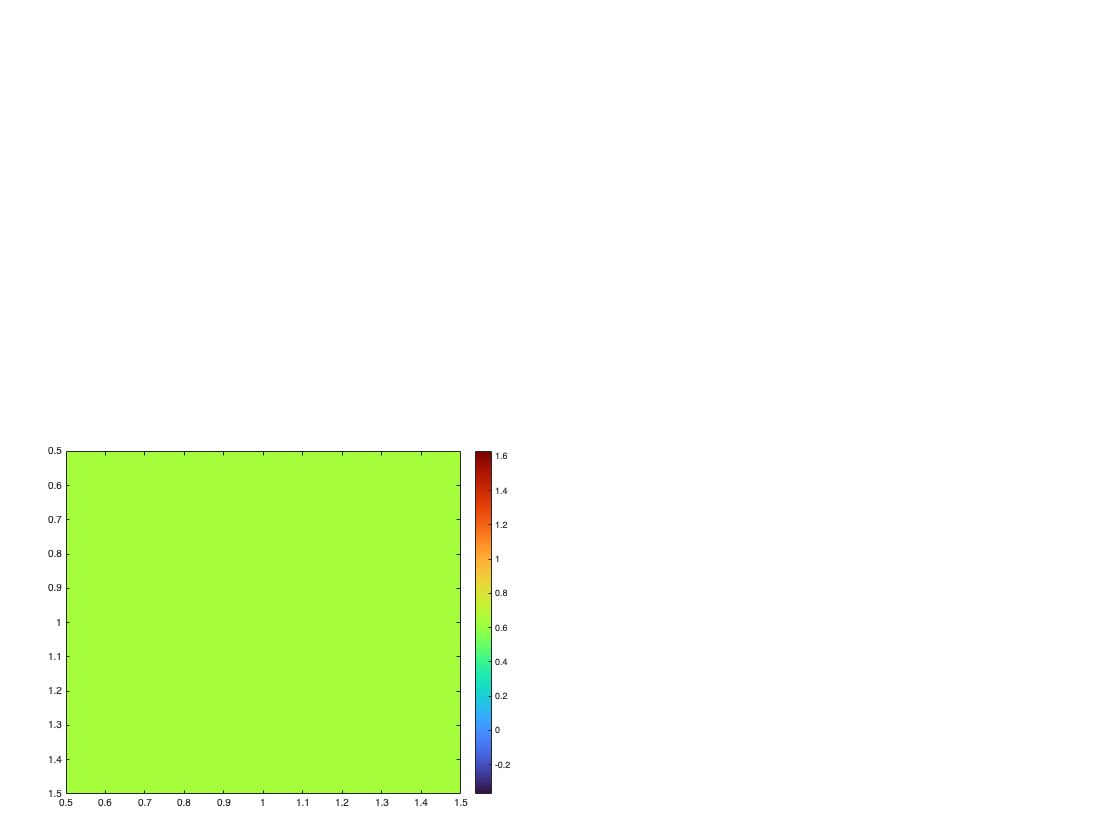

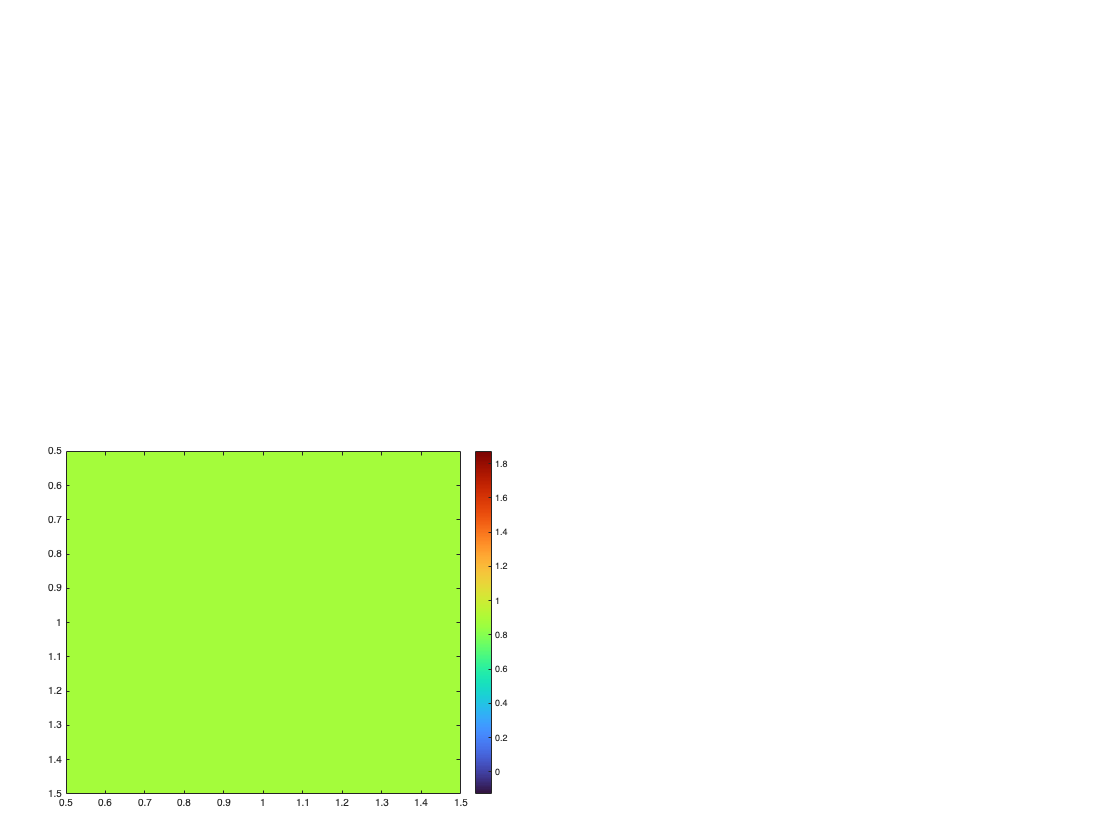

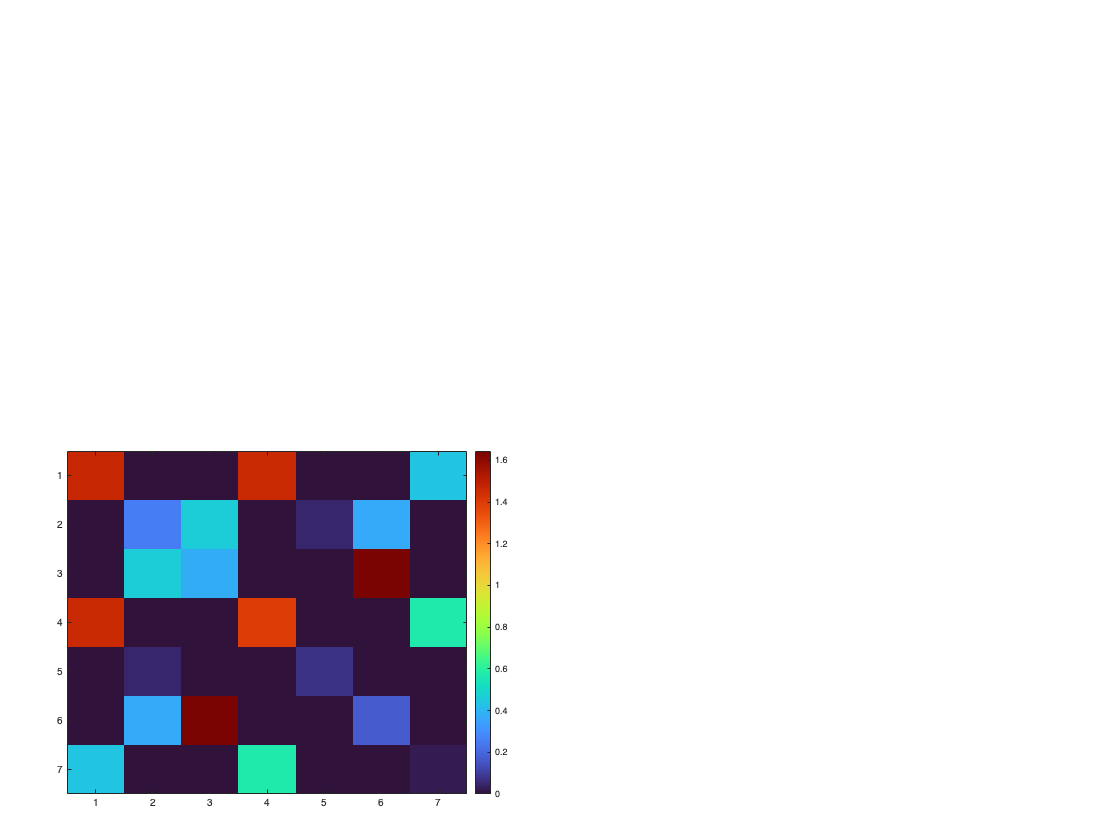

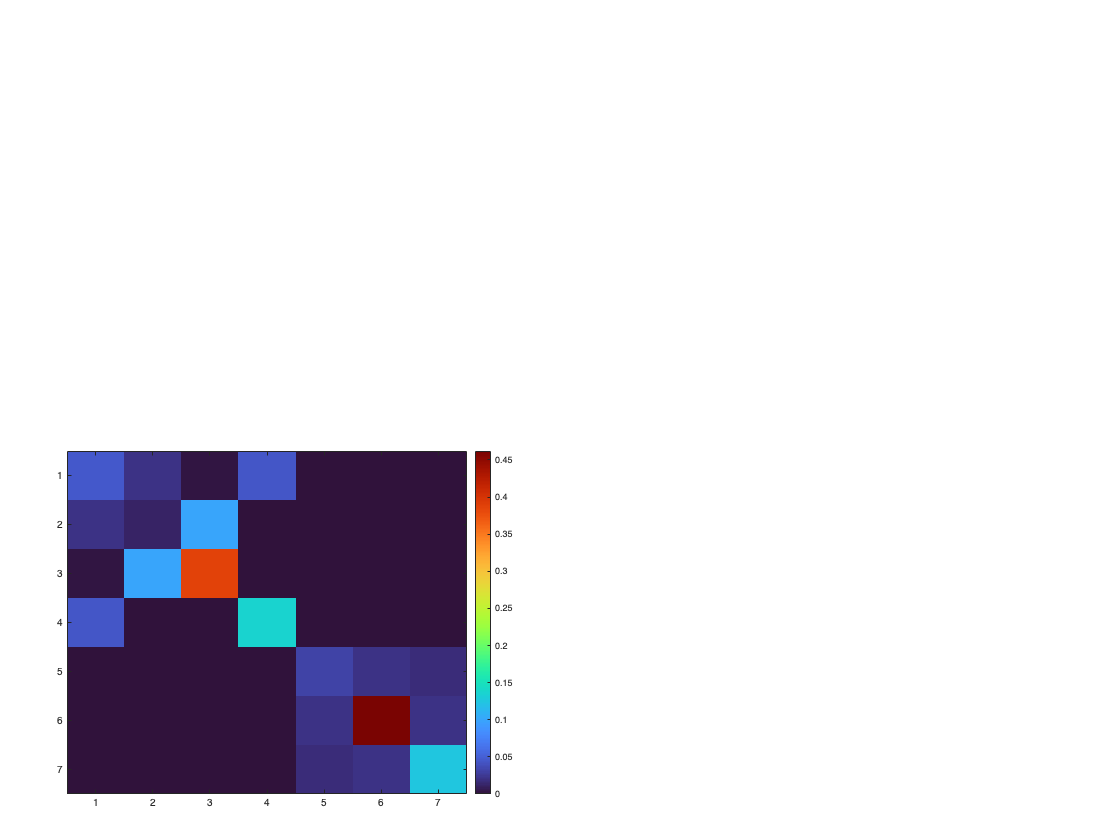

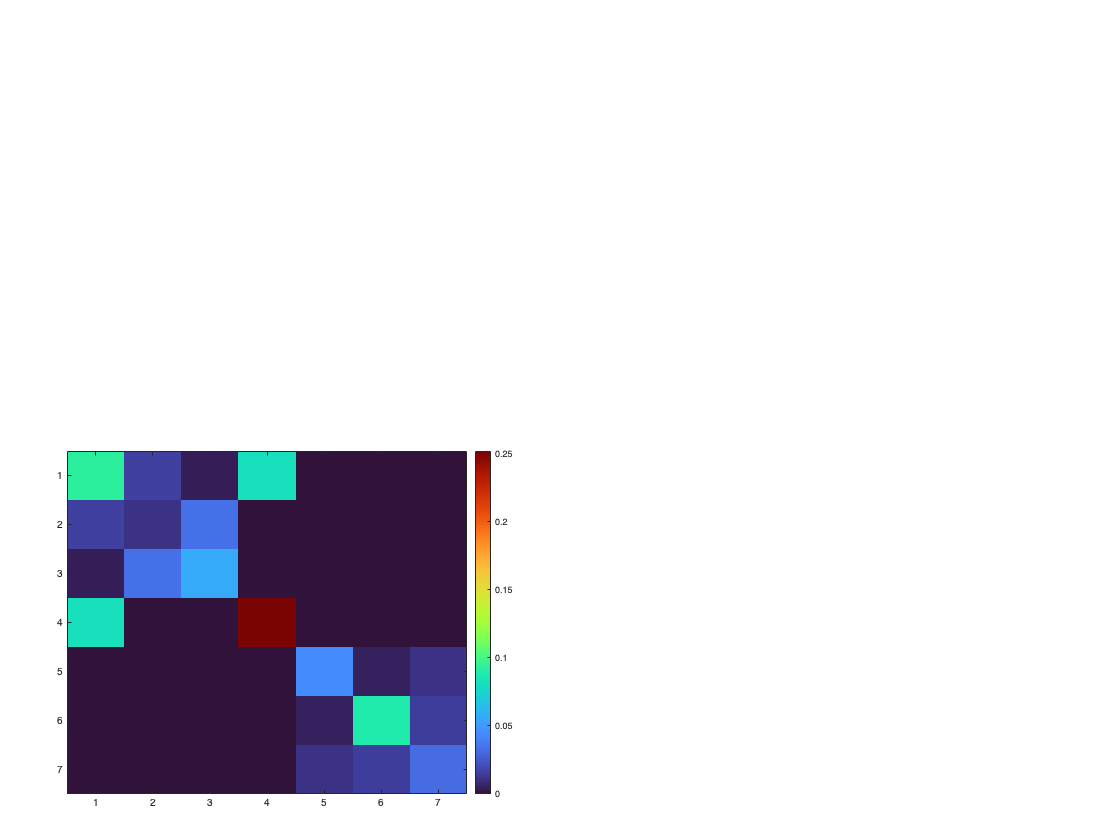

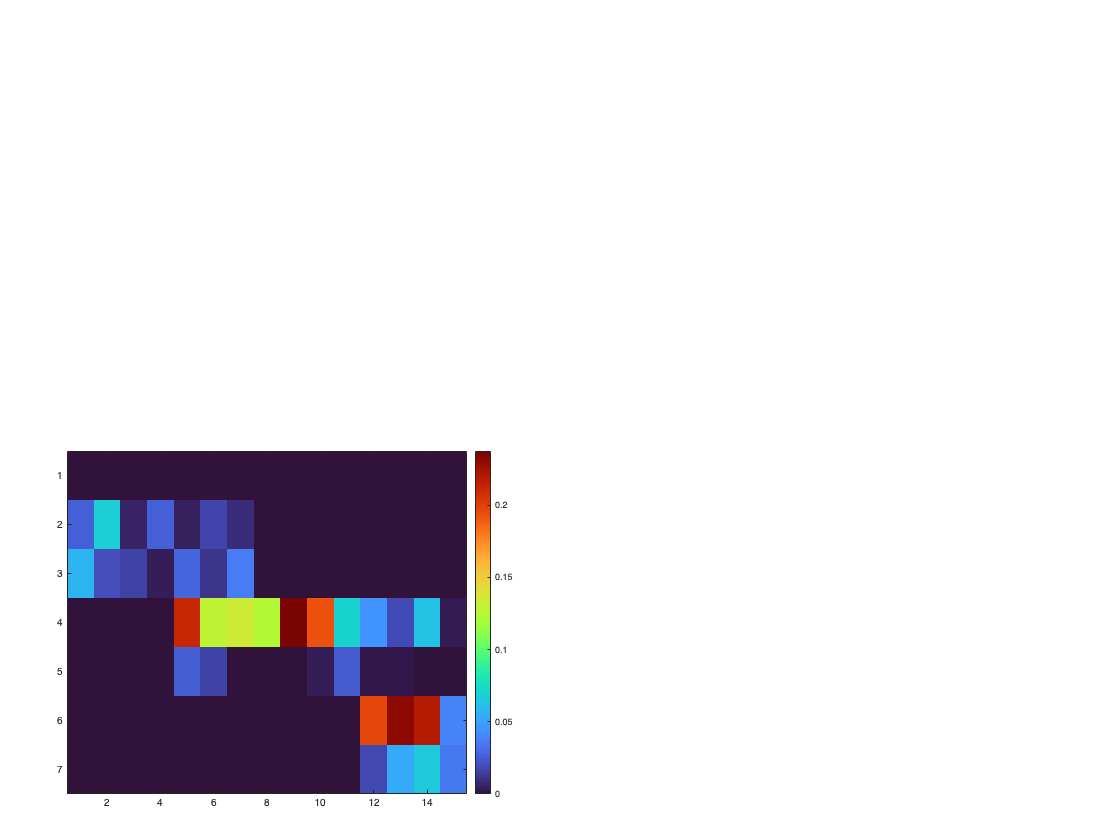

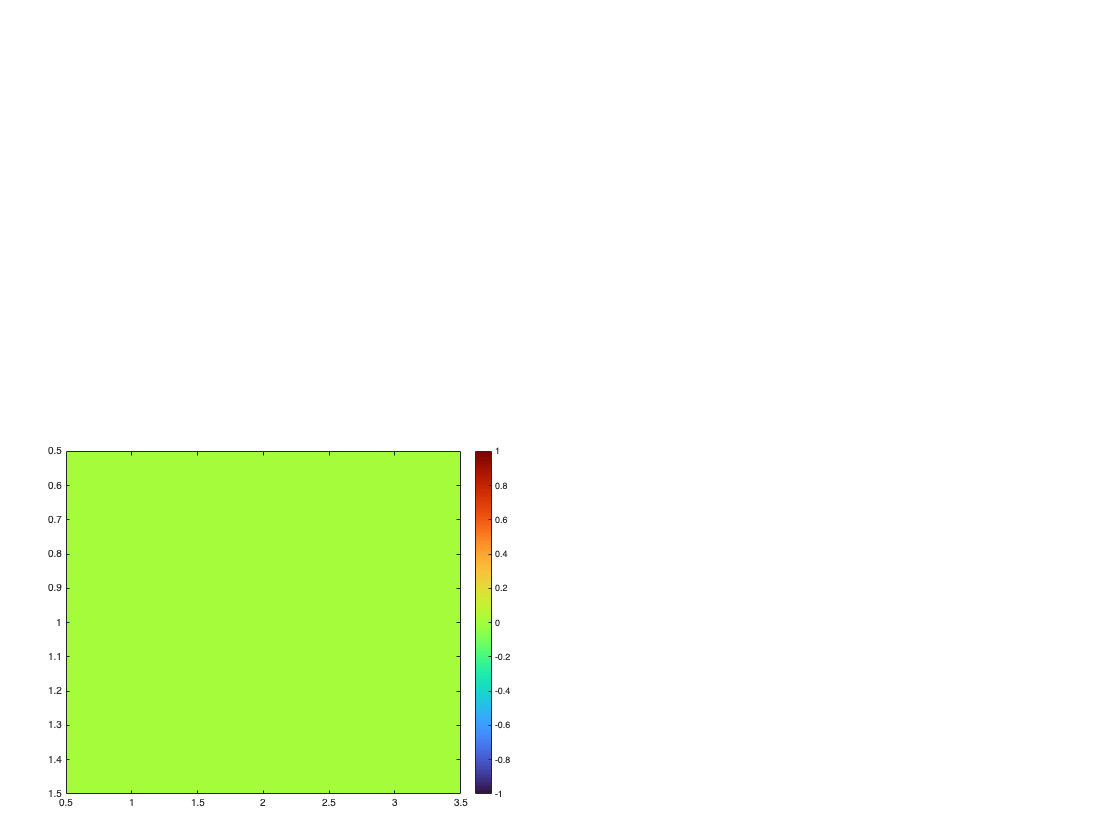

        else1
        imagesc(AIE_Org{m});
    end
    colormap("turbo");
    colorbar;
end